# CN7023 - AUTOMATED INDUSTRIAL METAL SURFACE DEFECT CLASSIFICATION

## Professional end-to-end MATLAB project

###  Models compared:

   1) Shallow CNN trained from scratch

   2) EfficientNet-B0 transfer learning

   3) AlexNet transfer learning

### Controlled epoch comparison:

   - 50 epochs versus 100 epochs for every architecture

   - The settings within each architecture remain fixed so that the effect

     of changing the epoch count can be interpreted fairly.

### Outputs:

   - Data-quality report

   - Dataset and split tables

   - Sample-image and class-distribution figures

   - Training and validation accuracy curves

   - Test accuracy comparison at 50 and 100 epochs

   - Absolute and row-normalized confusion matrices

   - Accuracy, balanced accuracy, precision, recall, specificity, F1-score,

     weighted F1-score, Cohen's kappa, and per-class metrics

   - Misclassifies-image table and montage

   - Grad-CAM explanations for the best validation model

   - Best trained network

### REQUIRED SOFTWARE:

   MATLAB R2024a or newer

   Deep Learning Toolbox

   EfficientNet-B0 and AlexNet support packages

### EXPECTED DATASET STRUCTURE:

   metal_surface_dataset/

       normal

       scratch

       crack

       rust

       hole

clear;
clc;
close all;


## 1.PROJECT RUN CONTROL

rng(7023,"twister");


DATASET_PATH = "C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive";

OUTPUT_DIR = fullfile(getenv("USERPROFILE"),"Documents","CN7023_Metal_Surface_Results");
if ~isfolder(OUTPUT_DIR)
    mkdir(OUTPUT_DIR);
end

RUN_DATA_PREPARATION = false;

RUN_SHALLOW_50       = false;
RUN_SHALLOW_100      = false;

RUN_EFFICIENTNET_50  = false;
RUN_EFFICIENTNET_100 = false;

RUN_ALEXNET_50       = false;
RUN_ALEXNET_100      = false;

RUN_FINAL_COMPARISON = true;

CACHE_DIR = fullfile(OUTPUT_DIR,"saved_progress");

if ~isfolder(CACHE_DIR)
    mkdir(CACHE_DIR);
end


PART 2–5: Load, clean, analyze and split


if RUN_DATA_PREPARATION
    % dataset preparation code
end


PART 6: Shallow CNN 50 epochs


if RUN_SHALLOW_50
    % training code
end


PART 7: Shallow CNN 100 epochs


if RUN_SHALLOW_100
    % training code
end


PART 8: EfficientNet 50 epochs


if RUN_EFFICIENTNET_50
    % training code
end


PART 9: EfficientNet 100 epochs


if RUN_EFFICIENTNET_100
    % training code
end


PART 10: AlexNet 50 epochs


if RUN_ALEXNET_50
    % training code
end


PART 11: AlexNet 100 epochs


if RUN_ALEXNET_100
    % training code
end


PART 12: Final comparison


if RUN_FINAL_COMPARISON
    % tables, graphs and comparison
end

## 2. REPRODUCIBLE PROJECT CONFIGURATION

% Your expected five classes.

EXPECTED_CLASSES = ["normal","scratch","crack","rust","hole"];

TRAIN_RATIO = 0.70;
VALIDATION_RATIO = 0.15;

% The remaining 0.15 is automatically used for testing.

MIN_IMAGE_SIDE = 32;

% Exact duplicate detection is useful for preventing train/test leakage.
% It can be disabled if hashing is not supported in your MATLAB session.
REMOVE_EXACT_DUPLICATES = true;

% Core mode performs six experiments:
% 3 models x {50,100 epochs}, using Adam.
%
% Extended mode adds another six SGDM experiments. Turn it on only after
% the core project runs successfully.
RUN_EXTENDED_SOLVER_COMPARISON = false;

% Set to true only to check that the whole program runs. It trains each
% architecture for two epochs and is not suitable for final results.
QUICK_TEST = false;

% "auto" uses a supported GPU when available and otherwise uses the CPU.
EXECUTION_ENVIRONMENT = "auto";

% Keeping this false avoids opening many windows. The script still exports
% clean training-history figures after each experiment.
SHOW_LIVE_TRAINING_WINDOWS = false;

% Saves only the best validation model to avoid producing several very
% large network files.
SAVE_BEST_NETWORK = true;

GENERATE_GRADCAM = true;

if ~isfolder(DATASET_PATH)
    error("Dataset folder not found: %s\nChange DATASET_PATH at the top of the script.",DATASET_PATH);
end

if ~isfolder(OUTPUT_DIR)
    mkdir(OUTPUT_DIR);
end

FIGURE_DIR = fullfile(OUTPUT_DIR,"figures");
TABLE_DIR = fullfile(OUTPUT_DIR,"tables");
RUN_DIR = fullfile(OUTPUT_DIR,"runs");

if ~isfolder(FIGURE_DIR); mkdir(FIGURE_DIR); end
if ~isfolder(TABLE_DIR);  mkdir(TABLE_DIR);  end
if ~isfolder(RUN_DIR);    mkdir(RUN_DIR);    end


diaryFile = fullfile(OUTPUT_DIR,"project_command_window_log.txt");
if isfile(diaryFile)
    delete(diaryFile);
end
diary(diaryFile);
diary on;

fprintf("\n============================================================\n");

fprintf("CN7023 METAL SURFACE DEFECT CLASSIFICATION PROJECT\n");

CN7023 METAL SURFACE DEFECT CLASSIFICATION PROJECT


fprintf("Started: %s\n",string(datetime("now")));

Started: 05-Aug-2026 15:22:59


fprintf("Dataset: %s\n",DATASET_PATH);

Dataset: C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive


fprintf("Output:  %s\n",OUTPUT_DIR);

Output:  C:\Users\User\Documents\CN7023_Metal_Surface_Results


fprintf("============================================================\n\n");

## 3. LOAD THE IMAGE DATASET

fileExtensions = [".jpg",".jpeg",".png",".bmp",".tif",".tiff"];

imdsRaw = imageDatastore(DATASET_PATH, ...
    IncludeSubfolders=true, ...
    LabelSource="foldernames", ...
    FileExtensions=fileExtensions);

if isempty(imdsRaw.Files)
    error("No supported image files were found in %s.",DATASET_PATH);
end

rawClassNames = string(categories(imdsRaw.Labels));

fprintf("Raw images found: %d\n",numel(imdsRaw.Files));

Raw images found: 15000


fprintf("Classes found: %d\n",numel(rawClassNames));

Classes found: 5


disp(rawClassNames);

    "crack"
    "hole"
    "normal"
    "rust"
    "scratch"




missingExpected = setdiff(lower(EXPECTED_CLASSES),lower(rawClassNames));
if ~isempty(missingExpected)
    warning("Expected class folder(s) not found: %s. Check folder spelling.", ...
        strjoin(missingExpected,", "));
end

## PART 4: INSPECT AND CLEAN DATASET — WITH CACHE



CACHE_FILE = fullfile(OUTPUT_DIR,"clean_dataset_cache.mat");

% Change this to true only when the dataset itself changes
REBUILD_CLEAN_CACHE = false;

if isfile(CACHE_FILE) && ~REBUILD_CLEAN_CACHE

    fprintf("\nLoading previously cleaned dataset...\n");

    load(CACHE_FILE, ...
        "qualityTable", ...
        "validImages", ...
        "cleanFiles", ...
        "cleanLabels");

    % Recreate the cleaned image datastore
    imds = imageDatastore(cellstr(cleanFiles));
    imds.Labels = categorical(cleanLabels);

    fprintf("Clean dataset loaded from cache.\n");
    fprintf("Number of clean images: %d\n",numel(imds.Files));

else

    fprintf("\nInspecting and cleaning the complete dataset...\n");
    fprintf("This may take time during the first run only.\n");

    files = string(imdsRaw.Files);
    labels = string(imdsRaw.Labels);

    numImages = numel(files);

    isReadable = false(numImages,1);
    isValidSize = false(numImages,1);
    isValidColour = false(numImages,1);

    imageHeight = nan(numImages,1);
    imageWidth = nan(numImages,1);
    imageChannels = nan(numImages,1);

    minimumImageSize = 32;

    for i = 1:numImages

        try
            info = imfinfo(files(i));

            imageHeight(i) = info(1).Height;
            imageWidth(i) = info(1).Width;

            % Reading the image verifies that it is not corrupt
            img = imread(files(i));

            isReadable(i) = true;

            % Check minimum dimensions
            isValidSize(i) = ...
                imageHeight(i) >= minimumImageSize && ...
                imageWidth(i) >= minimumImageSize;

            % Check supported image channels
            if ndims(img) == 2

                imageChannels(i) = 1;
                isValidColour(i) = true;

            elseif ndims(img) == 3 && ...
                    (size(img,3) == 3 || size(img,3) == 4)

                imageChannels(i) = size(img,3);
                isValidColour(i) = true;
            end

        catch imageError

            fprintf("Removed unreadable image: %s\n",files(i));
            fprintf("Reason: %s\n",imageError.message);
        end

        % Show progress every 500 images
        if mod(i,500) == 0 || i == numImages
            fprintf("Checked %d of %d images — %.1f%%\n", ...
                i,numImages,100*i/numImages);
        end
    end

    %% Create quality report

    qualityTable = table( ...
        files, ...
        labels, ...
        isReadable, ...
        imageHeight, ...
        imageWidth, ...
        imageChannels, ...
        isValidSize, ...
        isValidColour, ...
        'VariableNames', { ...
        'File', ...
        'Label', ...
        'Readable', ...
        'Height', ...
        'Width', ...
        'Channels', ...
        'ValidSize', ...
        'ValidColour'});

    %% Keep valid images

    validImages = ...
        isReadable & ...
        isValidSize & ...
        isValidColour;

    cleanFiles = files(validImages);
    cleanLabels = labels(validImages);

    imds = imageDatastore(cellstr(cleanFiles));
    imds.Labels = categorical(cleanLabels);

    fprintf("\nOriginal images: %d\n",numImages);
    fprintf("Clean images: %d\n",numel(cleanFiles));
    fprintf("Removed images: %d\n",sum(~validImages));

    %% Save reports

    writetable(qualityTable, ...
        fullfile(TABLE_DIR,"01_image_quality_report.csv"));

    writetable(qualityTable(~validImages,:), ...
        fullfile(TABLE_DIR,"02_removed_images.csv"));

    %% Save cache for future runs

    save(CACHE_FILE, ...
        "qualityTable", ...
        "validImages", ...
        "cleanFiles", ...
        "cleanLabels", ...
        "-v7.3");

    fprintf("\nClean dataset cache saved successfully:\n%s\n", ...
        CACHE_FILE);
end


Loading previously cleaned dataset...


Clean dataset loaded from cache.


Number of clean images: 15000


## PART 5: ANALYSE AND VISUALISE THE CLEAN DATASET



fprintf("\nAnalysing the cleaned dataset...\n");


Analysing the cleaned dataset...


## 5.1 Count the number of images in each class



classCountTable = countEachLabel(imds);

% Convert labels to strings for saving and plotting
classCountTable.Label = string(classCountTable.Label);

% Calculate the percentage of images in each class
classCountTable.Percentage = ...
    100 .* classCountTable.Count ./ sum(classCountTable.Count);

disp("Clean dataset class distribution:");

Clean dataset class distribution:


disp(classCountTable);

      Label      Count    Percentage
    _________    _____    __________

    "crack"      3000         20    
    "hole"       3000         20    
    "normal"     3000         20    
    "rust"       3000         20    
    "scratch"    3000         20    




% Save the class-count table
writetable(classCountTable, ...
    fullfile(TABLE_DIR,"04_clean_class_distribution.csv"));


## 5.2 Display the number of classes and total images



numberOfClasses = height(classCountTable);
totalImages = sum(classCountTable.Count);

fprintf("Number of classes: %d\n",numberOfClasses);

Number of classes: 5


fprintf("Total cleaned images: %d\n",totalImages);

Total cleaned images: 15000


## 5.3 Check class balance



largestClass = max(classCountTable.Count);
smallestClass = min(classCountTable.Count);

imbalanceRatio = largestClass / smallestClass;

fprintf("Largest class size: %d images\n",largestClass);

Largest class size: 3000 images


fprintf("Smallest class size: %d images\n",smallestClass);

Smallest class size: 3000 images


fprintf("Class imbalance ratio: %.2f\n",imbalanceRatio);

Class imbalance ratio: 1.00



if imbalanceRatio <= 1.20
    fprintf("The dataset is well balanced.\n");

elseif imbalanceRatio <= 1.50
    fprintf("The dataset has mild class imbalance.\n");

else
    warning("The dataset has noticeable class imbalance.");
end

The dataset is well balanced.


## 5.4 Plot class distribution

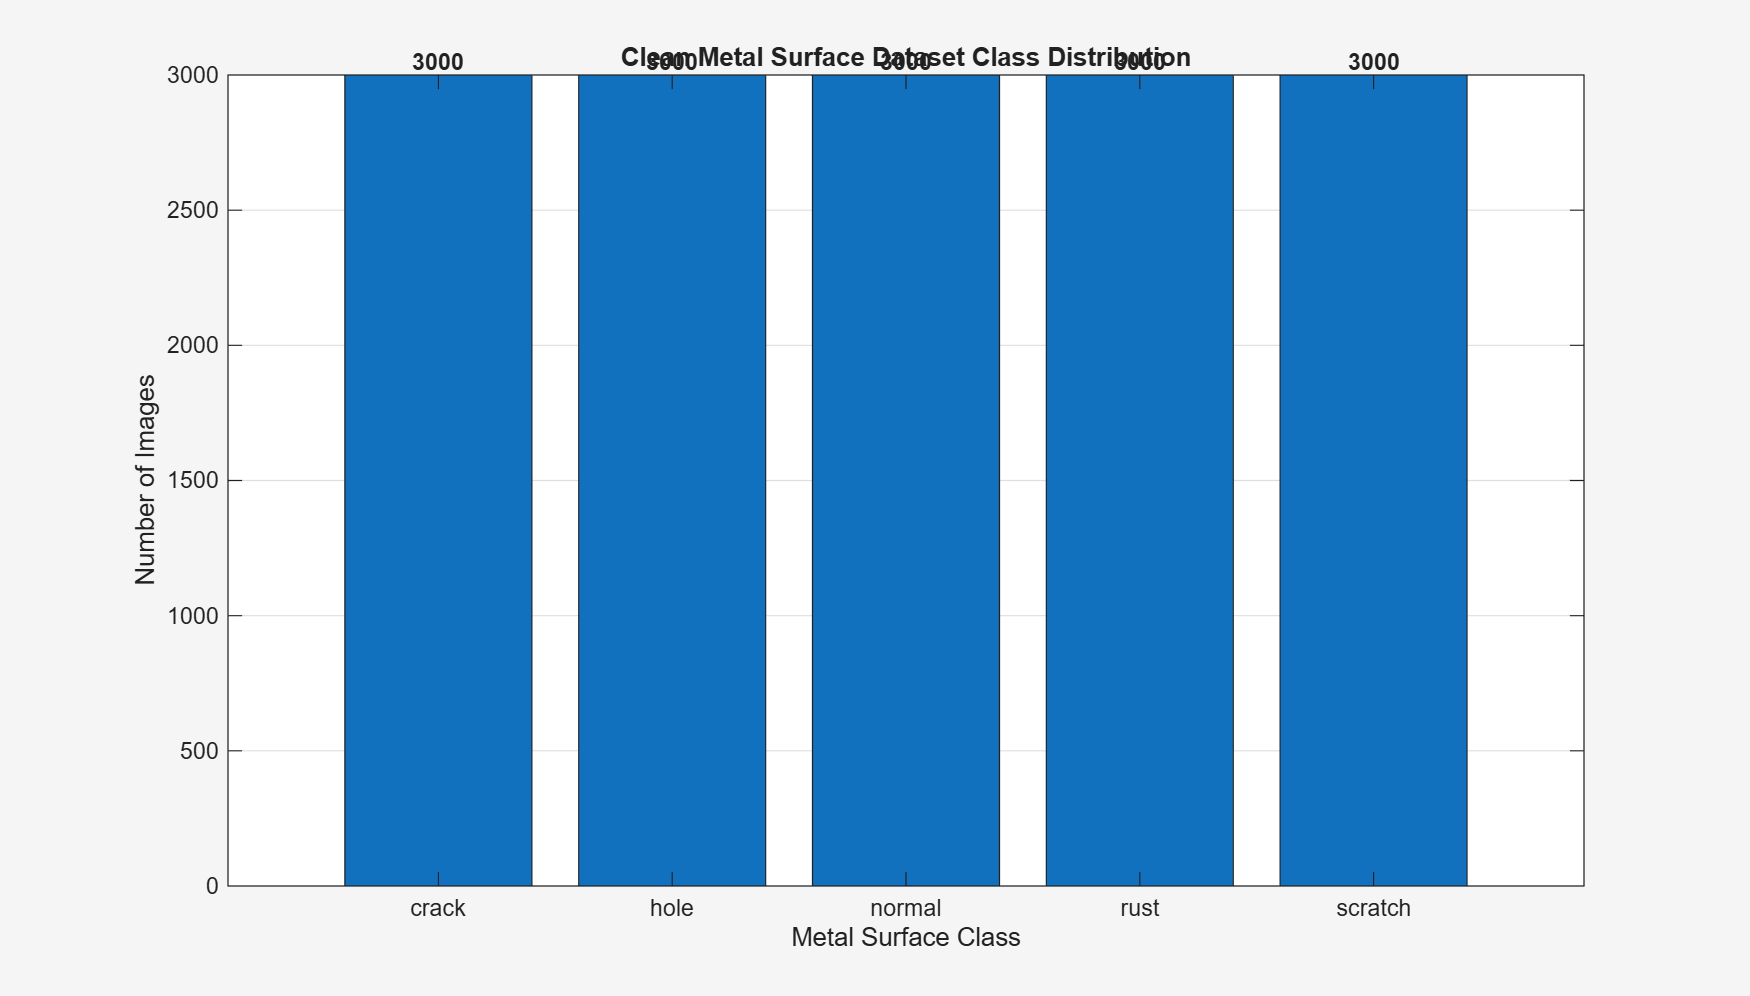



fig = figure( ...
    "Visible","on", ...
    "Position",[100 100 1000 600]);

bar( ...
    categorical(classCountTable.Label), ...
    classCountTable.Count);

xlabel("Metal Surface Class");
ylabel("Number of Images");
title("Clean Metal Surface Dataset Class Distribution");
grid on;

% Add image counts above the bars
for i = 1:height(classCountTable)

    text( ...
        i, ...
        classCountTable.Count(i), ...
        string(classCountTable.Count(i)), ...
        "HorizontalAlignment","center", ...
        "VerticalAlignment","bottom", ...
        "FontWeight","bold");
end

exportgraphics( ...
    fig, ...
    fullfile(FIGURE_DIR,"01_class_distribution.png"), ...
    "Resolution",300);

## 5.5 Analyse image dimensions



% Use the validImages variable created in Part 3
validQuality = qualityTable(validImages,:);

% Ensure only valid numerical dimensions are analysed
validQuality = validQuality( ...
    ~isnan(validQuality.Height) & ...
    ~isnan(validQuality.Width),:);

fprintf("\nImage dimension statistics:\n");


Image dimension statistics:



averageHeight = mean(validQuality.Height);
averageWidth = mean(validQuality.Width);

minimumHeight = min(validQuality.Height);
maximumHeight = max(validQuality.Height);

minimumWidth = min(validQuality.Width);
maximumWidth = max(validQuality.Width);

fprintf("Average image height: %.2f pixels\n",averageHeight);

Average image height: 256.00 pixels


fprintf("Average image width: %.2f pixels\n",averageWidth);

Average image width: 256.00 pixels


fprintf("Minimum image size: %d x %d pixels\n", ...
    minimumWidth,minimumHeight);

Minimum image size: 256 x 256 pixels


fprintf("Maximum image size: %d x %d pixels\n", ...
    maximumWidth,maximumHeight);

Maximum image size: 256 x 256 pixels


## 5.6 Create image-dimension summary by class



classNames = unique(string(validQuality.Label));

summaryClass = strings(numel(classNames),1);

imageCount = zeros(numel(classNames),1);

meanHeight = zeros(numel(classNames),1);
minimumHeightByClass = zeros(numel(classNames),1);
maximumHeightByClass = zeros(numel(classNames),1);

meanWidth = zeros(numel(classNames),1);
minimumWidthByClass = zeros(numel(classNames),1);
maximumWidthByClass = zeros(numel(classNames),1);

for i = 1:numel(classNames)

    currentClass = classNames(i);

    classRows = string(validQuality.Label) == currentClass;

    classHeights = validQuality.Height(classRows);
    classWidths = validQuality.Width(classRows);

    summaryClass(i) = currentClass;
    imageCount(i) = sum(classRows);

    meanHeight(i) = mean(classHeights);
    minimumHeightByClass(i) = min(classHeights);
    maximumHeightByClass(i) = max(classHeights);

    meanWidth(i) = mean(classWidths);
    minimumWidthByClass(i) = min(classWidths);
    maximumWidthByClass(i) = max(classWidths);
end

dimensionSummary = table( ...
    summaryClass, ...
    imageCount, ...
    meanHeight, ...
    minimumHeightByClass, ...
    maximumHeightByClass, ...
    meanWidth, ...
    minimumWidthByClass, ...
    maximumWidthByClass, ...
    'VariableNames', { ...
    'Class', ...
    'ImageCount', ...
    'MeanHeight', ...
    'MinimumHeight', ...
    'MaximumHeight', ...
    'MeanWidth', ...
    'MinimumWidth', ...
    'MaximumWidth'});

disp("Image dimension summary by class:");

Image dimension summary by class:


disp(dimensionSummary);

      Class      ImageCount    MeanHeight    MinimumHeight    MaximumHeight    MeanWidth    MinimumWidth    MaximumWidth
    _________    __________    __________    _____________    _____________    _________    ____________    ____________

    "crack"         3000          256             256              256            256           256             256     
    "hole"          3000          256             256              256            256           256             256     
    "normal"        3000          256             256              256            256           256             256     
    "rust"          3000          256             256              256            256           256             256     
 


writetable( ...
    dimensionSummary, ...
    fullfile(TABLE_DIR,"05_image_dimension_summary.csv"));


## 5.7 Plot image width and height distributions

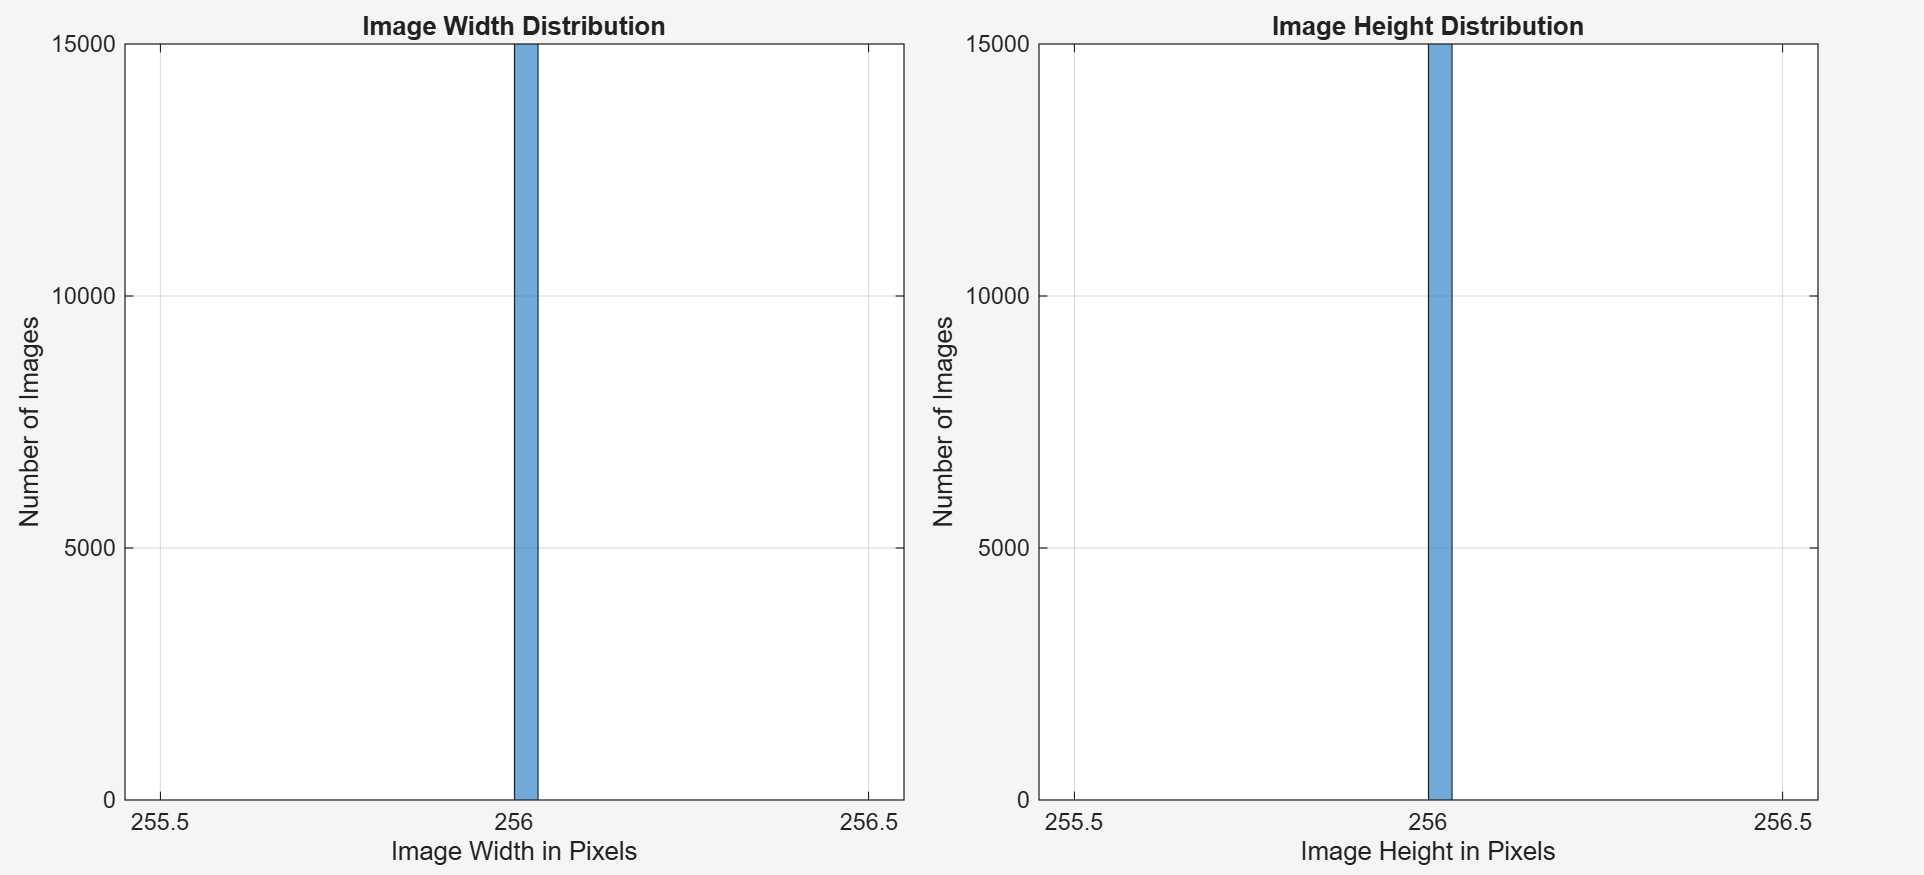



fig = figure( ...
    "Visible","on", ...
    "Position",[100 100 1100 500]);

tiledlayout(1,2, ...
    "TileSpacing","compact", ...
    "Padding","compact");

nexttile;

histogram(validQuality.Width,30);

xlabel("Image Width in Pixels");
ylabel("Number of Images");
title("Image Width Distribution");
grid on;

nexttile;

histogram(validQuality.Height,30);

xlabel("Image Height in Pixels");
ylabel("Number of Images");
title("Image Height Distribution");
grid on;

exportgraphics( ...
    fig, ...
    fullfile(FIGURE_DIR,"02_image_dimension_distribution.png"), ...
    "Resolution",300);

## 5.8 Display sample images from each class

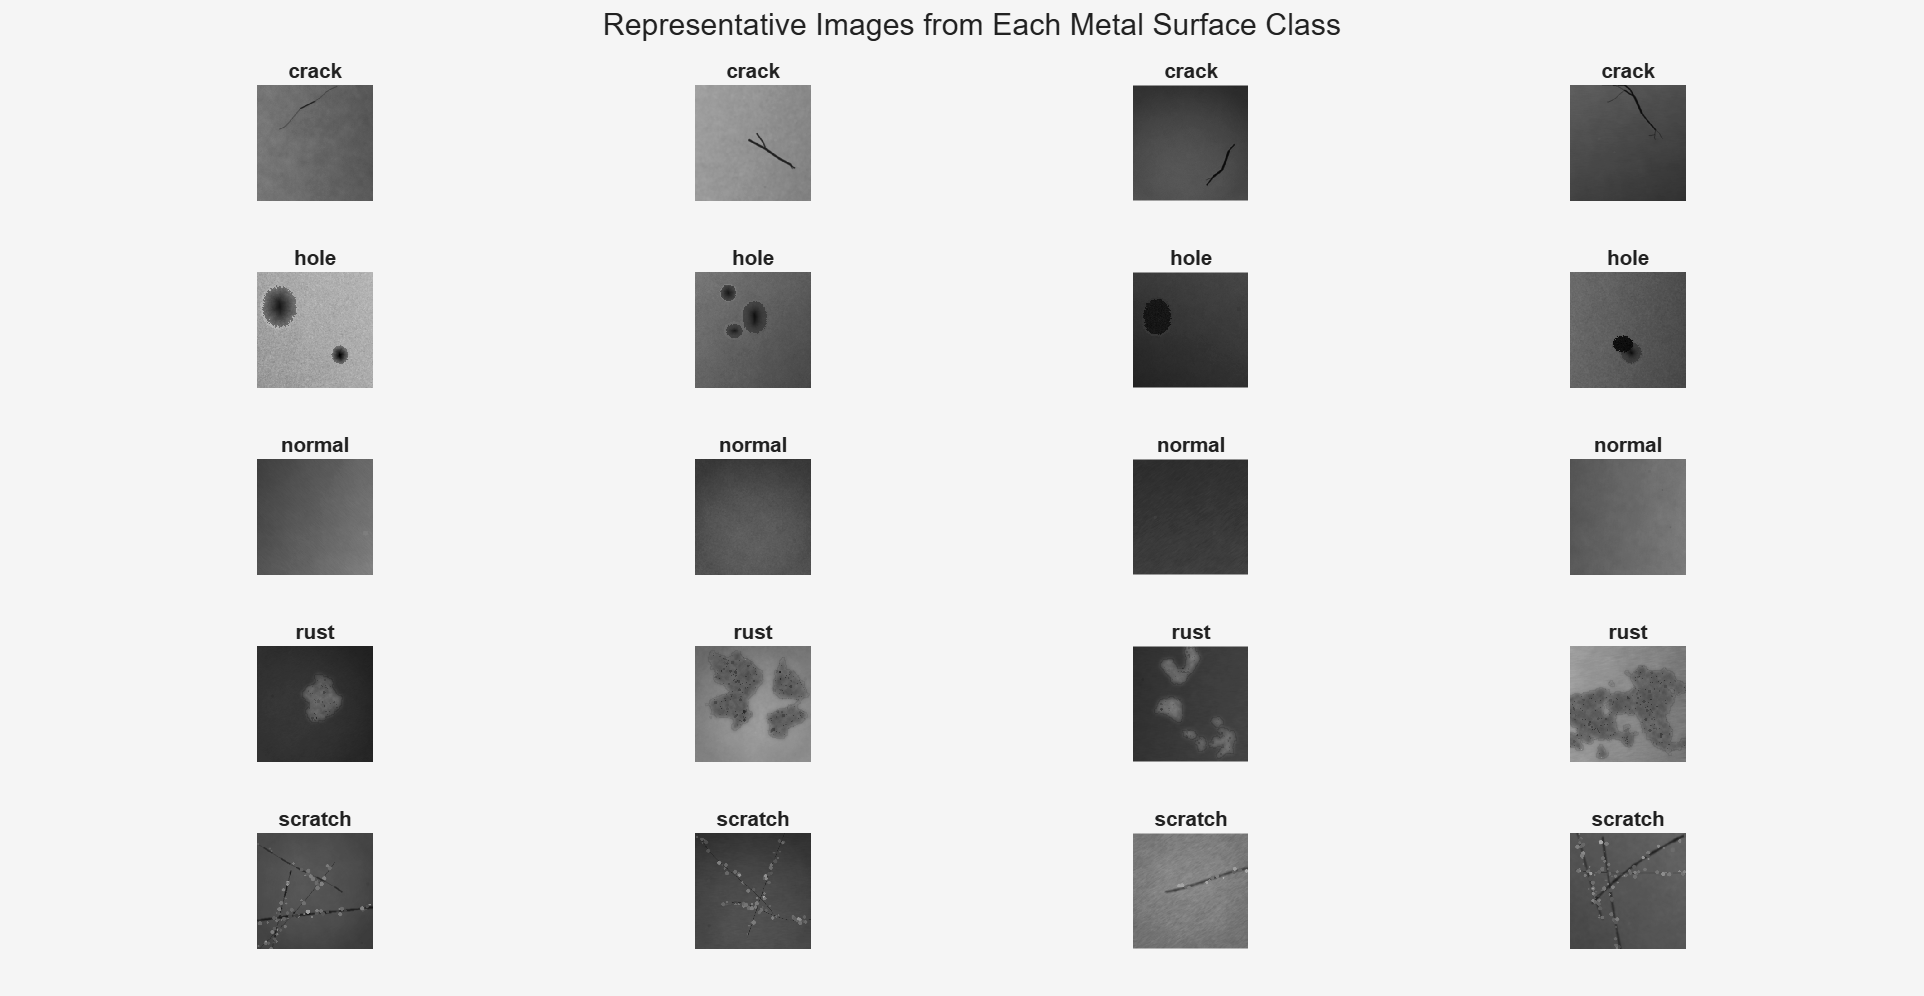



imagesPerClass = 4;
classNames = string(categories(imds.Labels));

fig = figure( ...
    "Visible","on", ...
    "Position",[100 100 1200 900]);

layout = tiledlayout( ...
    fig, ...
    numel(classNames), ...
    imagesPerClass, ...
    "TileSpacing","compact", ...
    "Padding","compact");

for classIndex = 1:numel(classNames)

    currentClass = classNames(classIndex);

    classImageIndices = find( ...
        string(imds.Labels) == currentClass);

    numberToDisplay = min( ...
        imagesPerClass, ...
        numel(classImageIndices));

    if numberToDisplay > 0

        selectedIndices = classImageIndices( ...
            randperm( ...
                numel(classImageIndices), ...
                numberToDisplay));

    else
        selectedIndices = [];
    end

    for imageIndex = 1:imagesPerClass

        ax = nexttile(layout);

        if imageIndex <= numberToDisplay

            imageData = readimage( ...
                imds, ...
                selectedIndices(imageIndex));

            imshow(imageData,"Parent",ax);

            title( ...
                ax, ...
                currentClass, ...
                "Interpreter","none");

        else
            axis(ax,"off");
        end
    end
end

title(layout, ...
    "Representative Images from Each Metal Surface Class");

drawnow;

outputFile = fullfile( ...
    FIGURE_DIR, ...
    "03_sample_images_by_class.png");

exportgraphics( ...
    layout, ...
    outputFile, ...
    "Resolution",300);


fprintf("\nSample image figure saved to:\n%s\n",outputFile);


Sample image figure saved to:
C:\Users\User\Documents\CN7023_Metal_Surface_Results\figures\03_sample_images_by_class.png


fprintf("Dataset analysis completed successfully.\n");

Dataset analysis completed successfully.


## 6. STRATIFIED TRAINING, VALIDATION, AND TEST SPLIT


[imdsTrain,imdsValidation,imdsTest] = splitEachLabel( ...
    imds, ...
    TRAIN_RATIO, ...
    VALIDATION_RATIO, ...
    "randomized");

trainTable = countEachLabel(imdsTrain);
validationTable = countEachLabel(imdsValidation);
testTable = countEachLabel(imdsTest);

splitTable = table( ...
    string(trainTable.Label), ...
    trainTable.Count, ...
    validationTable.Count, ...
    testTable.Count, ...
    'VariableNames', { ...
    'Class', ...
    'TrainingImages', ...
    'ValidationImages', ...
    'TestImages'});

splitTable.TotalImages = ...
    splitTable.TrainingImages + ...
    splitTable.ValidationImages + ...
    splitTable.TestImages;

disp(splitTable);

      Class      TrainingImages    ValidationImages    TestImages    TotalImages
    _________    ______________    ________________    __________    ___________

    "crack"           2100               450              450           3000    
    "hole"            2100               450              450           3000    
    "normal"          2100               450              450           3000    
    "rust"            2100               450              450           3000    
    "scratch"         2100               450              450           3000    




writetable( ...
    splitTable, ...
    fullfile(TABLE_DIR,"06_train_validation_test_split.csv"));
%% Create split manifest

trainManifest = table( ...
    string(imdsTrain.Files), ...
    string(imdsTrain.Labels), ...
    repmat("Training",numel(imdsTrain.Files),1), ...
    'VariableNames', {'File','Label','Split'});

validationManifest = table( ...
    string(imdsValidation.Files), ...
    string(imdsValidation.Labels), ...
    repmat("Validation",numel(imdsValidation.Files),1), ...
    'VariableNames', {'File','Label','Split'});

testManifest = table( ...
    string(imdsTest.Files), ...
    string(imdsTest.Labels), ...
    repmat("Testing",numel(imdsTest.Files),1), ...
    'VariableNames', {'File','Label','Split'});

splitManifest = [ ...
    trainManifest;
    validationManifest;
    testManifest];

disp(splitManifest(1:min(10,height(splitManifest)),:));

                                                             File                                                              Label       Split   
    ______________________________________________________________________________________________________________________    _______    __________

    "C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive\industrial_defect_dataset\train\crack\crack_00000.png"    "crack"    "Training"
    "C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive\industrial_defect_dataset\train\crack\crack_00001.png"    "crack"    "Training"
    "C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive\industrial_defect_dataset\train\crack\crack_00004.png"    "crack"    "Training"
    "C:\Users\User\Desktop\CN7023 (Machine Vision)\DataSets\archive\industrial_defect_dataset\train\crack\crack_00008.png"    "crack"    "Training"
    "C:\U


writetable( ...
    splitManifest, ...
    fullfile(TABLE_DIR,"07_reproducible_split_manifest.csv"));

fprintf("Split manifest saved successfully.\n");

Split manifest saved successfully.



if numel(unique(splitManifest.File)) ~= height(splitManifest)
    error("Data leakage detected: one or more images appear in multiple splits.");
else
    fprintf("No data leakage detected between training, validation and test sets.\n");
end

No data leakage detected between training, validation and test sets.



fprintf("\nSplit completed successfully:\n");


Split completed successfully:


fprintf("Training images:   %d\n",numel(imdsTrain.Files));

Training images:   10500


fprintf("Validation images: %d\n",numel(imdsValidation.Files));

Validation images: 2250


fprintf("Testing images:    %d\n",numel(imdsTest.Files));

Testing images:    2250


## 6. DEFINE THE EXPERIMENT TABLE

%% 6. DEFINE SIX EXPERIMENTS AND CLEAN OLD CACHE
%
% Two Shallow CNN experiments
% Two EfficientNet-B0 experiments
% Two AlexNet experiments
%
% IMPORTANT:
% Running this section deletes previous Part 7 models, checkpoints,
% figures and cached results.

fprintf("\n============================================================\n");

fprintf("PART 6: EXPERIMENT CONFIGURATION AND CACHE CLEANING\n");

PART 6: EXPERIMENT CONFIGURATION AND CACHE CLEANING


fprintf("============================================================\n");


%% 6.1 CACHE CONTROL

CLEAN_CACHE = false;

if ~exist("OUTPUT_DIR","var")
    OUTPUT_DIR = fullfile(pwd,"CN7023_Results");
end

TABLE_DIR = fullfile(OUTPUT_DIR,"tables");
RUN_DIR = fullfile(OUTPUT_DIR,"training_runs");
CACHE_DIR = fullfile(OUTPUT_DIR,"saved_progress");

if ~isfolder(OUTPUT_DIR)
    mkdir(OUTPUT_DIR);
end

if ~isfolder(TABLE_DIR)
    mkdir(TABLE_DIR);
end

%% 6.2 KEEP OR DELETE CACHE

if CLEAN_CACHE

    fprintf("\nDeleting previous training cache and results...\n");

    if isfolder(RUN_DIR)
        rmdir(RUN_DIR,"s");
    end

    if isfolder(CACHE_DIR)
        rmdir(CACHE_DIR,"s");
    end

    oldCSV = fullfile( ...
        TABLE_DIR, ...
        "08_experiment_configuration.csv");

    oldResultsCSV = fullfile( ...
        TABLE_DIR, ...
        "09_all_model_results.csv");

    if isfile(oldCSV)
        delete(oldCSV);
    end

    if isfile(oldResultsCSV)
        delete(oldResultsCSV);
    end

    mkdir(RUN_DIR);
    mkdir(CACHE_DIR);

    fprintf("Old cache deleted successfully.\n");
    fprintf("Training will start from zero.\n");

else

    if ~isfolder(RUN_DIR)
        mkdir(RUN_DIR);
    end

    if ~isfolder(CACHE_DIR)
        mkdir(CACHE_DIR);
    end

    fprintf("\nExisting cache and trained models are kept.\n");
    fprintf("Part 7 will load completed experiments.\n");

end


Existing cache and trained models are kept.


Part 7 will load completed experiments.



%% 6.3 Define six experiments

modelNames = [
    "ShallowCNN"
    "ShallowCNN"
    "EfficientNetB0"
    "EfficientNetB0"
    "AlexNet"
    "AlexNet"
];

% Different maximum epoch values
epochValues = [
    50
    100
    50
    100
    50
    100
];

% Different optimisers
solverNames = [
    "sgdm"
    "adam"
    "sgdm"
    "adam"
    "sgdm"
    "adam"
];

% Different learning rates
learningRates = [
    1e-3      % Shallow CNN, 50 epochs
    1e-4      % Shallow CNN, 100 epochs

    1e-4      % EfficientNet-B0, 50 epochs
    3e-5      % EfficientNet-B0, 100 epochs

    1e-4      % AlexNet, 50 epochs
    3e-5      % AlexNet, 100 epochs
];

% Mini-batch sizes
miniBatchSizes = [
    64
    64

    32
    32

    64
    64
];

% L2 regularization

l2Values = repmat(1e-4,6,1);

% First configuration of each architecture is marked primary

isPrimaryValues = [
    true
    false
    true
    false
    true
    false
];

%% 6.4 Create correct experiment names

experimentIDs = [
    "ShallowCNN_50ep_SGDM_LR001"
    "ShallowCNN_100ep_ADAM_LR0001"

    "EfficientNetB0_50ep_SGDM_LR0001"
    "EfficientNetB0_100ep_ADAM_LR00003"

    "AlexNet_50ep_SGDM_LR0001"
    "AlexNet_100ep_ADAM_LR00003"
];

%% 6.5 Build experiment table

experimentTable = table( ...
    experimentIDs, ...
    modelNames, ...
    epochValues, ...
    solverNames, ...
    learningRates, ...
    miniBatchSizes, ...
    l2Values, ...
    isPrimaryValues, ...
    'VariableNames', { ...
    'ExperimentID', ...
    'Model', ...
    'Epochs', ...
    'Solver', ...
    'InitialLearnRate', ...
    'MiniBatchSize', ...
    'L2Regularization', ...
    'IsPrimary'});

%% 6.6 Optional quick test

if ~exist("QUICK_TEST","var")
    QUICK_TEST = false;
end

if QUICK_TEST

    fprintf("\nQUICK TEST ENABLED\n");
    fprintf("Only one experiment per architecture will run.\n");

    experimentTable = experimentTable( ...
        experimentTable.IsPrimary,:);

    experimentTable.Epochs(:) = 2;

    experimentTable.ExperimentID = ...
        experimentTable.Model + ...
        "_2ep_" + ...
        upper(experimentTable.Solver) + ...
        "_SMOKETEST";
end

%% 6.7 Display and save the experiment table

fprintf("\nFINAL EXPERIMENT TABLE:\n");


FINAL EXPERIMENT TABLE:


disp(experimentTable);

               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    _________

    "ShallowCNN_50ep_SGDM_LR001"           "ShallowCNN"          50      "sgdm"          0.001              64               0.0001           true   
    "ShallowCNN_100ep_ADAM_LR0001"         "ShallowCNN"         100      "adam"         0.0001              64               0.0001           false  
    "EfficientNetB0_50ep_SGDM_LR0001"      "EfficientNetB0"      50      "sgdm"         0.0001              32               0.


writetable( ...
    experimentTable, ...
    fullfile(TABLE_DIR,"08_experiment_configuration.csv"));

save( ...
    fullfile(CACHE_DIR,"experiment_configuration.mat"), ...
    "experimentTable", ...
    "QUICK_TEST");

fprintf("\nExperiment configuration saved successfully.\n");


Experiment configuration saved successfully.


fprintf("Now run Part 7.\n");

Now run Part 7.


## 7. TRAIN, VALIDATE, TEST, AND SAVE EVERY EXPERIMENT


%% 7. TRAIN, VALIDATE, TEST, CACHE AND COMPARE ALL EXPERIMENTS
%
% Run Part 6 before running this section.
%
% Required variables:
% experimentTable
% imdsTrain
% imdsValidation
% imdsTest
% classNames
% OUTPUT_DIR
% TABLE_DIR
% RUN_DIR
% CACHE_DIR
% EXECUTION_ENVIRONMENT

fprintf("\n============================================================\n");

fprintf("PART 7: TRAINING SIX MODEL CONFIGURATIONS\n");

PART 7: TRAINING SIX MODEL CONFIGURATIONS


fprintf("============================================================\n");


%% 7.1 Verify required variables

requiredVariables = [
    "experimentTable"
    "imdsTrain"
    "imdsValidation"
    "imdsTest"
    "classNames"
    "OUTPUT_DIR"
    "TABLE_DIR"
    "RUN_DIR"
    "CACHE_DIR"
];

for variableIndex = 1:numel(requiredVariables)

    currentVariable = requiredVariables(variableIndex);

    if ~exist(currentVariable,"var")
        error( ...
            "Required variable '%s' is missing. Run Parts 1–6 first.", ...
            currentVariable);
    end
end

if ~exist("EXECUTION_ENVIRONMENT","var")
    EXECUTION_ENVIRONMENT = "auto";
end

classNames = string(classNames);
numClasses = numel(classNames);
numExperiments = height(experimentTable);

%% 7.2 Check dataset class distributions

fprintf("\nTraining dataset:\n");


Training dataset:


disp(countEachLabel(imdsTrain));

     Label     Count
    _______    _____

    crack      2100 
    hole       2100 
    normal     2100 
    rust       2100 
    scratch    2100 



fprintf("Validation dataset:\n");

Validation dataset:


disp(countEachLabel(imdsValidation));

     Label     Count
    _______    _____

    crack       450 
    hole        450 
    normal      450 
    rust        450 
    scratch     450 




fprintf("Testing dataset:\n");

Testing dataset:


disp(countEachLabel(imdsTest));

     Label     Count
    _______    _____

    crack       450 
    hole        450 
    normal      450 
    rust        450 
    scratch     450 



EXPERIMENT 1 OF 6


Experiment: ShallowCNN_50ep_SGDM_LR001


Model: ShallowCNN


Epochs: 50


Solver: SGDM


Learning rate: 0.00100000


Mini-batch size: 64


Loading completed experiment from cache...


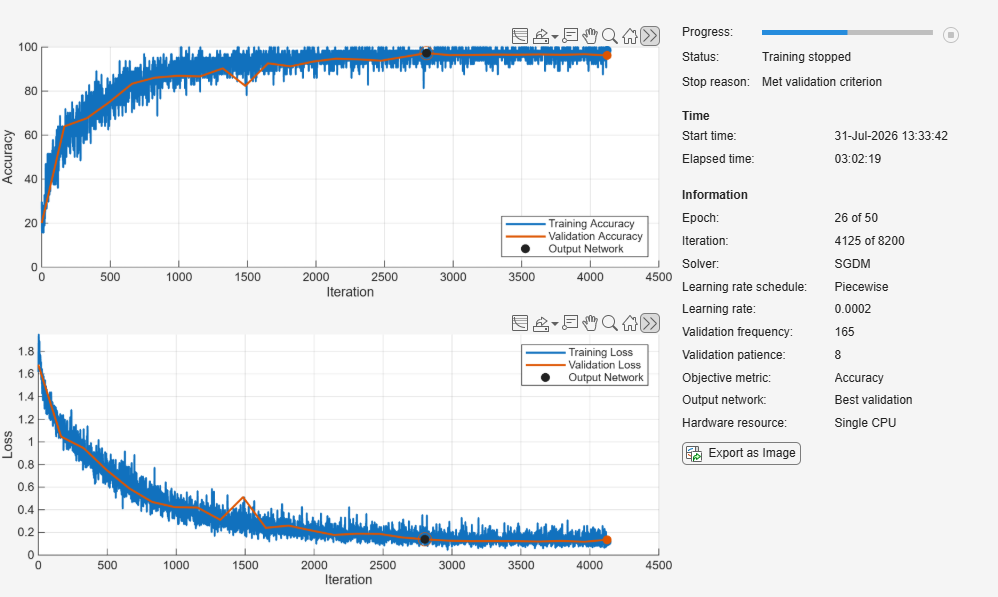

Cached experiment loaded.


Validation accuracy: 97.29%


Test accuracy: 96.89%


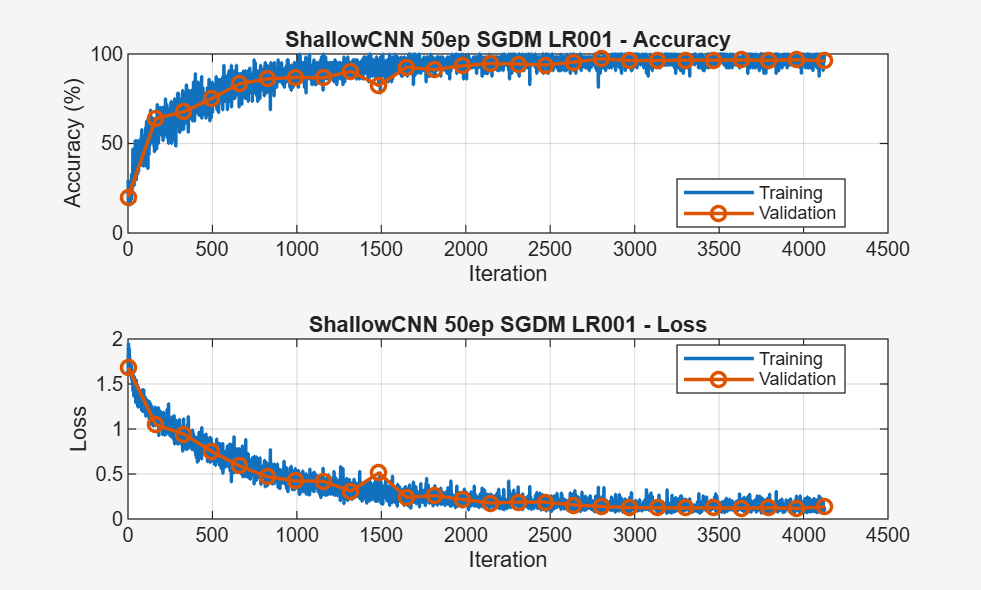

Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


            ExperimentID               Model        Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    ____________________________    ____________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________    ___________

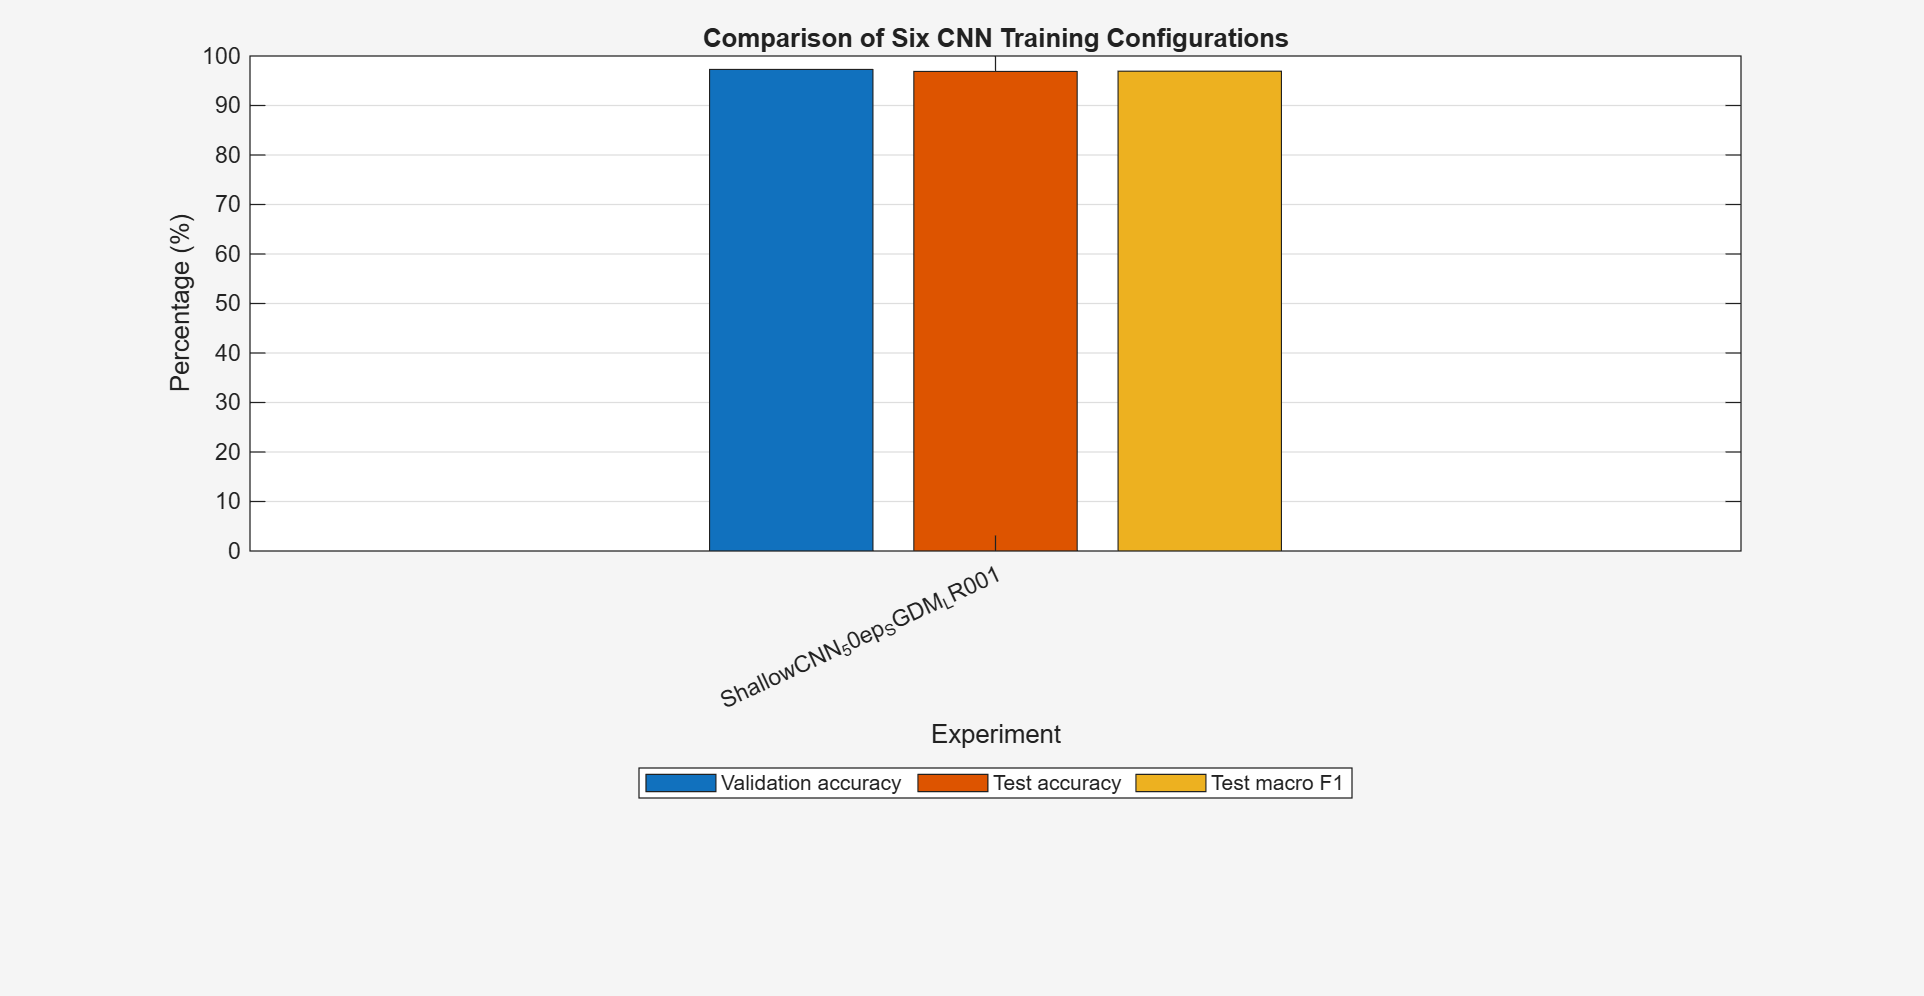

BEST MODEL SELECTED USING VALIDATION MACRO F1


            ExperimentID               Model        Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ____________________________    ____________    ______    ______    ________________    _____________    ________________    _________

    "ShallowCNN_50ep_SGDM_LR001"    "ShallowCNN"      50      "sgdm"         0.001               64               0.0001           true   



Best validation macro F1: 97.32%


Best validation accuracy: 97.29%


Corresponding test accuracy: 96.89%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results


EXPERIMENT 2 OF 6


Experiment: ShallowCNN_100ep_ADAM_LR0001


Model: ShallowCNN


Epochs: 100


Solver: ADAM


Learning rate: 0.00010000


Mini-batch size: 64


Loading completed experiment from cache...


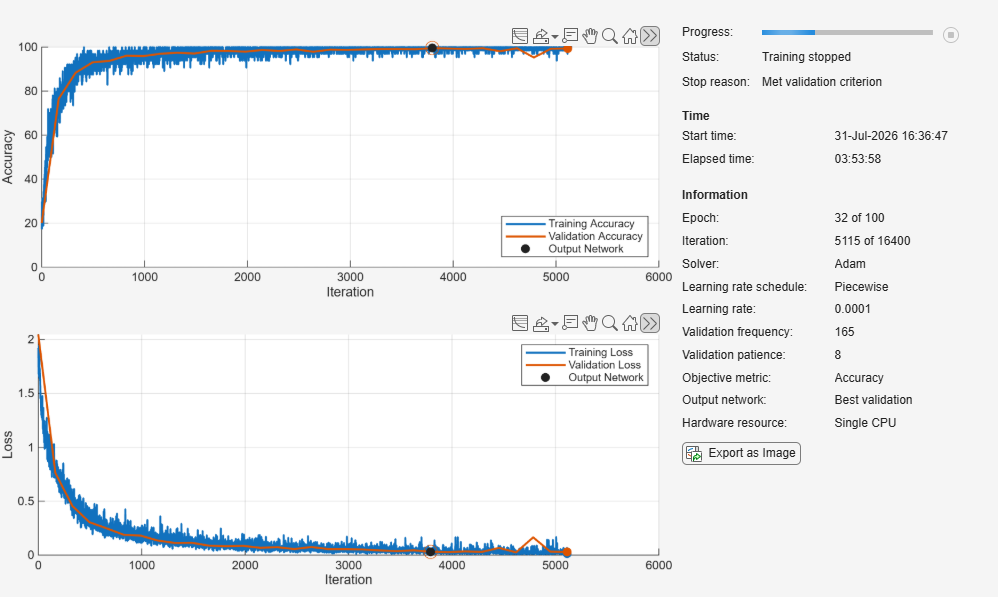

Cached experiment loaded.


Validation accuracy: 99.51%


Test accuracy: 99.56%


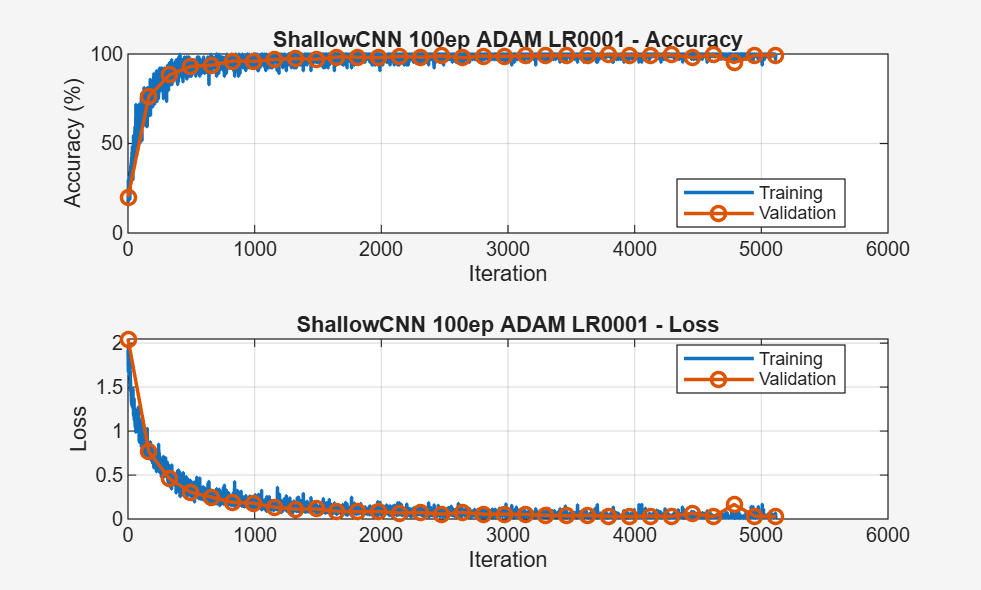

Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


             ExperimentID                Model        Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    ______________________________    ____________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________    _______

BEST MODEL SELECTED USING VALIDATION MACRO F1


             ExperimentID                Model        Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ______________________________    ____________    ______    ______    ________________    _____________    ________________    _________

    "ShallowCNN_100ep_ADAM_LR0001"    "ShallowCNN"     100      "adam"         0.0001              64               0.0001           false  



Best validation macro F1: 99.51%


Best validation accuracy: 99.51%


Corresponding test accuracy: 99.56%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results


EXPERIMENT 3 OF 6


Experiment: EfficientNetB0_50ep_SGDM_LR0001


Model: EfficientNetB0


Epochs: 50


Solver: SGDM


Learning rate: 0.00010000


Mini-batch size: 32


Loading completed experiment from cache...


Cached experiment loaded.


Validation accuracy: 99.87%


Test accuracy: 99.87%


Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


              ExperimentID                    Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    _________________________________    ________________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________    <

BEST MODEL SELECTED USING VALIDATION MACRO F1


              ExperimentID                    Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    _________________________________    ________________    ______    ______    ________________    _____________    ________________    _________

    "EfficientNetB0_50ep_SGDM_LR0001"    "EfficientNetB0"      50      "sgdm"         0.0001              32               0.0001           true   



Best validation macro F1: 99.87%


Best validation accuracy: 99.87%


Corresponding test accuracy: 99.87%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results


EXPERIMENT 4 OF 6


Experiment: EfficientNetB0_100ep_ADAM_LR00003


Model: EfficientNetB0


Epochs: 100


Solver: ADAM


Learning rate: 0.00003000


Mini-batch size: 32


Loading completed experiment from cache...


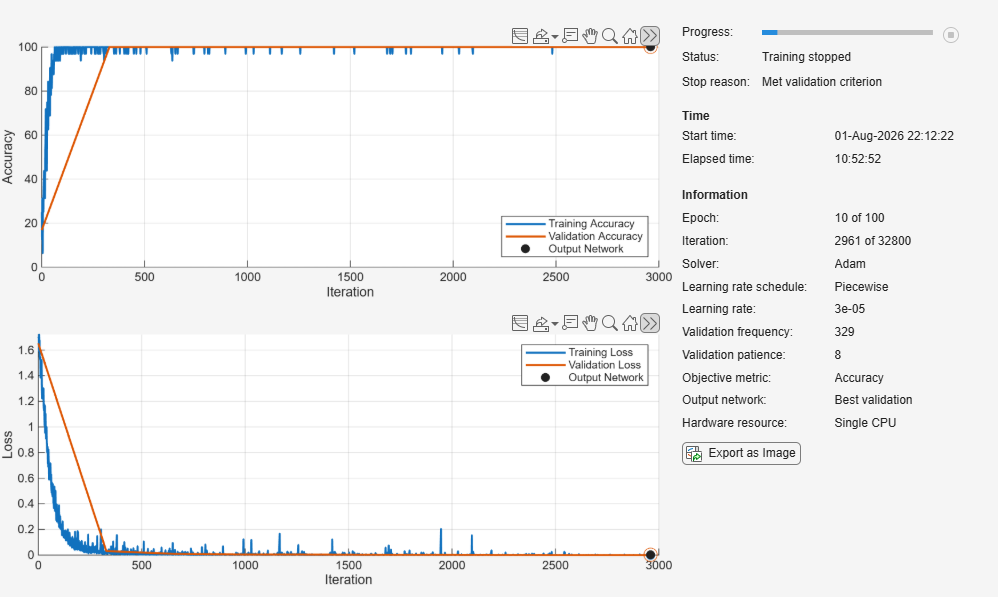

Cached experiment loaded.


Validation accuracy: 100.00%


Test accuracy: 100.00%


Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________ 

BEST MODEL SELECTED USING VALIDATION MACRO F1


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    _________

    "EfficientNetB0_100ep_ADAM_LR00003"    "EfficientNetB0"     100      "adam"         3e-05               32               0.0001           false  



Best validation macro F1: 100.00%


Best validation accuracy: 100.00%


Corresponding test accuracy: 100.00%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results


EXPERIMENT 5 OF 6


Experiment: AlexNet_50ep_SGDM_LR0001


Model: AlexNet


Epochs: 50


Solver: SGDM


Learning rate: 0.00010000


Mini-batch size: 64


Loading completed experiment from cache...


Cached experiment loaded.


Validation accuracy: 99.47%


Test accuracy: 99.42%


Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________ 

BEST MODEL SELECTED USING VALIDATION MACRO F1


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    _________

    "EfficientNetB0_100ep_ADAM_LR00003"    "EfficientNetB0"     100      "adam"         3e-05               32               0.0001           false  



Best validation macro F1: 100.00%


Best validation accuracy: 100.00%


Corresponding test accuracy: 100.00%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results


EXPERIMENT 6 OF 6


Experiment: AlexNet_100ep_ADAM_LR00003


Model: AlexNet


Epochs: 100


Solver: ADAM


Learning rate: 0.00003000


Mini-batch size: 64


Loading completed experiment from cache...


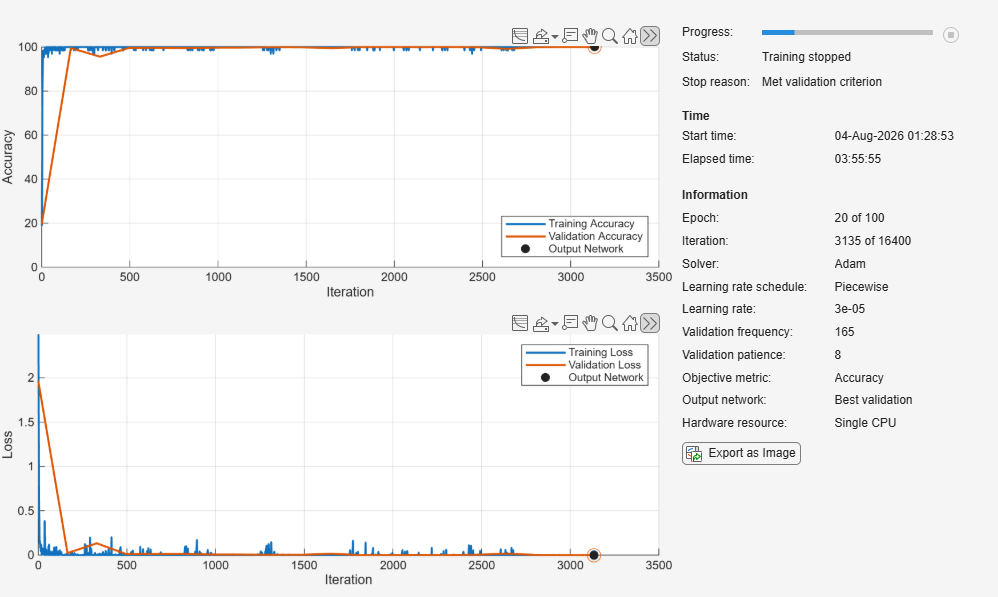

Cached experiment loaded.


Validation accuracy: 100.00%


Test accuracy: 99.91%


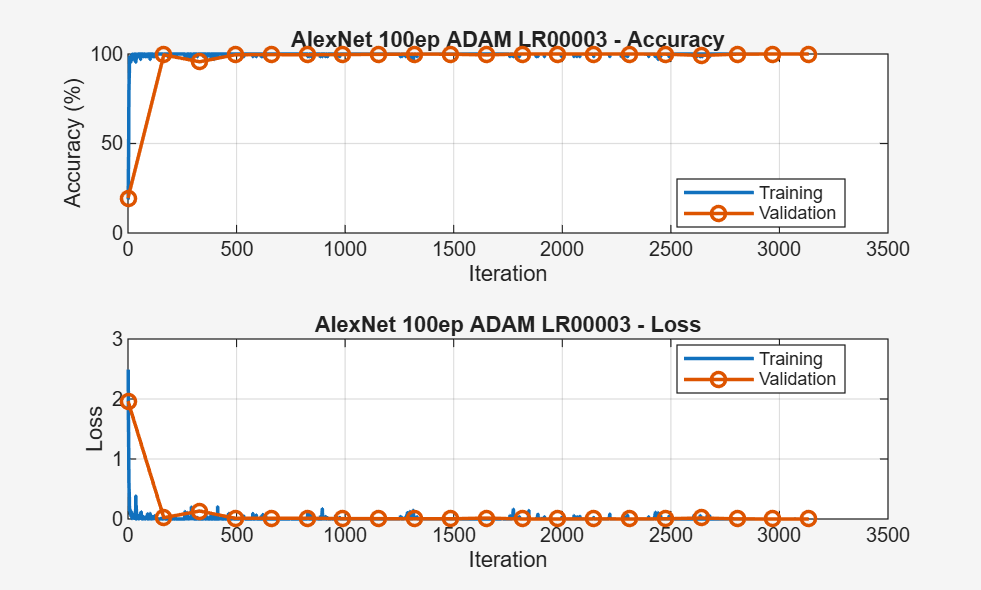

Training graph saved successfully.


FINAL SIX-EXPERIMENT COMPARISON


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    ValidationAccuracy    ValidationMacroF1    TestAccuracy    BalancedAccuracy    MacroPrecision    MacroRecall    MacroSpecificity    MacroF1    WeightedF1    CohensKappa    TrainingMinutes
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    __________________    _________________    ____________ 

BEST MODEL SELECTED USING VALIDATION MACRO F1


               ExperimentID                     Model          Epochs    Solver    InitialLearnRate    MiniBatchSize    L2Regularization    IsPrimary
    ___________________________________    ________________    ______    ______    ________________    _____________    ________________    _________

    "EfficientNetB0_100ep_ADAM_LR00003"    "EfficientNetB0"     100      "adam"         3e-05               32               0.0001           false  



Best validation macro F1: 100.00%


Best validation accuracy: 100.00%


Corresponding test accuracy: 100.00%



All experiment results were saved in:
C:\Users\User\Documents\CN7023_Metal_Surface_Results



if numel(categories(imdsTrain.Labels)) ~= numClasses
    error("Training data does not contain the expected number of classes.");
end

if numel(categories(imdsValidation.Labels)) ~= numClasses
    error("Validation data does not contain the expected number of classes.");
end

if numel(categories(imdsTest.Labels)) ~= numClasses
    error("Test data does not contain the expected number of classes.");
end

%% 7.3 Prepare result storage

resultRows = struct([]);

bestValidationAccuracy = -Inf;
bestValidationMacroF1 = -Inf;

bestNet = [];
bestExperiment = table();
bestTestPredictions = categorical();
bestTestScores = [];
bestTestAccuracy = NaN;
bestRunFolder = "";

%% 7.4 Run every experiment

for experimentIndex = 1:numExperiments

    config = experimentTable(experimentIndex,:);

    runID = string(config.ExperimentID);
    modelName = string(config.Model);
    solverName = lower(string(config.Solver));

    currentEpochs = config.Epochs;
    currentLearningRate = config.InitialLearnRate;
    currentMiniBatchSize = config.MiniBatchSize;
    currentL2 = config.L2Regularization;

    currentRunFolder = fullfile(RUN_DIR,runID);
    checkpointFolder = fullfile(currentRunFolder,"checkpoints");

    if ~isfolder(currentRunFolder)
        mkdir(currentRunFolder);
    end

    if ~isfolder(checkpointFolder)
        mkdir(checkpointFolder);
    end

    cacheFile = fullfile( ...
        currentRunFolder, ...
        runID + "_complete_results.mat");

    fprintf("\n\n============================================================\n");
    fprintf("EXPERIMENT %d OF %d\n",experimentIndex,numExperiments);
    fprintf("Experiment: %s\n",runID);
    fprintf("Model: %s\n",modelName);
    fprintf("Epochs: %d\n",currentEpochs);
    fprintf("Solver: %s\n",upper(solverName));
    fprintf("Learning rate: %.8f\n",currentLearningRate);
    fprintf("Mini-batch size: %d\n",currentMiniBatchSize);
    fprintf("============================================================\n");

    %% 7.5 Load completed cache when available

    if isfile(cacheFile)

        fprintf("Loading completed experiment from cache...\n");

        savedData = load(cacheFile);

        trainedNet = savedData.trainedNet;
        trainingInfo = savedData.trainingInfo;

        validationAccuracy = savedData.validationAccuracy;
        validationMacroF1 = savedData.validationMacroF1;

        testAccuracy = savedData.testAccuracy;
        testBalancedAccuracy = savedData.testBalancedAccuracy;
        testMacroPrecision = savedData.testMacroPrecision;
        testMacroRecall = savedData.testMacroRecall;
        testMacroSpecificity = savedData.testMacroSpecificity;
        testMacroF1 = savedData.testMacroF1;
        testWeightedF1 = savedData.testWeightedF1;
        cohensKappa = savedData.cohensKappa;

        testScores = savedData.testScores;
        testPredictions = savedData.testPredictions;
        testCM = savedData.testCM;

        trainingMinutes = savedData.trainingMinutes;
        inputSize = savedData.inputSize;

        fprintf("Cached experiment loaded.\n");
        fprintf("Validation accuracy: %.2f%%\n",validationAccuracy);
        fprintf("Test accuracy: %.2f%%\n",testAccuracy);

    else

        %% 7.6 Build a fresh network

        switch modelName

            case "ShallowCNN"

                inputSize = [128 128 3];

                layers = [
                    imageInputLayer( ...
                        inputSize, ...
                        Normalization="rescale-zero-one", ...
                        Name="input")

                    convolution2dLayer( ...
                        3,32, ...
                        Padding="same", ...
                        WeightsInitializer="he", ...
                        Name="conv1")

                    batchNormalizationLayer(Name="bn1")
                    reluLayer(Name="relu1")
                    maxPooling2dLayer(2,Stride=2,Name="pool1")

                    convolution2dLayer( ...
                        3,64, ...
                        Padding="same", ...
                        WeightsInitializer="he", ...
                        Name="conv2")

                    batchNormalizationLayer(Name="bn2")
                    reluLayer(Name="relu2")
                    maxPooling2dLayer(2,Stride=2,Name="pool2")

                    convolution2dLayer( ...
                        3,128, ...
                        Padding="same", ...
                        WeightsInitializer="he", ...
                        Name="conv3")

                    batchNormalizationLayer(Name="bn3")
                    reluLayer(Name="relu3")
                    maxPooling2dLayer(2,Stride=2,Name="pool3")

                    convolution2dLayer( ...
                        3,256, ...
                        Padding="same", ...
                        WeightsInitializer="he", ...
                        Name="conv4")

                    batchNormalizationLayer(Name="bn4")
                    reluLayer(Name="relu4")

                    globalAveragePooling2dLayer( ...
                        Name="globalAveragePooling")

                    dropoutLayer(0.40,Name="dropout")

                    fullyConnectedLayer( ...
                        numClasses, ...
                        WeightsInitializer="he", ...
                        Name="classification")

                    softmaxLayer(Name="softmax")
                ];

                net = dlnetwork(layers);

            case "EfficientNetB0"

                net = imagePretrainedNetwork( ...
                    "efficientnetb0", ...
                    NumClasses=numClasses);

                inputSize = net.Layers(1).InputSize;

            case "AlexNet"

                net = imagePretrainedNetwork( ...
                    "alexnet", ...
                    NumClasses=numClasses);

                inputSize = net.Layers(1).InputSize;

            otherwise

                error("Unknown model name: %s",modelName);
        end

        fprintf("Fresh model created successfully.\n");
        fprintf("Input size: %d x %d x %d\n", ...
            inputSize(1),inputSize(2),inputSize(3));

        %% 7.7 Create image datastores

        augmenter = imageDataAugmenter( ...
            RandXReflection=true, ...
            RandRotation=[-5 5], ...
            RandXTranslation=[-3 3], ...
            RandYTranslation=[-3 3]);

        augTrain = augmentedImageDatastore( ...
            inputSize(1:2), ...
            imdsTrain, ...
            DataAugmentation=augmenter, ...
            ColorPreprocessing="gray2rgb");

        augValidation = augmentedImageDatastore( ...
            inputSize(1:2), ...
            imdsValidation, ...
            ColorPreprocessing="gray2rgb");

        augTest = augmentedImageDatastore( ...
            inputSize(1:2), ...
            imdsTest, ...
            ColorPreprocessing="gray2rgb");

        %% 7.8 Calculate validation frequency

        iterationsPerEpoch = max( ...
            1, ...
            ceil(numel(imdsTrain.Files)/currentMiniBatchSize));

        validationFrequency = iterationsPerEpoch;

        fprintf("Iterations per epoch: %d\n",iterationsPerEpoch);

        %% 7.9 Create training options

        learningRateDropPeriod = max( ...
            5, ...
            round(currentEpochs/3));

        if solverName == "adam"

            options = trainingOptions("adam", ...
                MaxEpochs=currentEpochs, ...
                MiniBatchSize=currentMiniBatchSize, ...
                InitialLearnRate=currentLearningRate, ...
                LearnRateSchedule="piecewise", ...
                LearnRateDropPeriod=learningRateDropPeriod, ...
                LearnRateDropFactor=0.20, ...
                L2Regularization=currentL2, ...
                GradientThreshold=5, ...
                Shuffle="every-epoch", ...
                ValidationData=augValidation, ...
                ValidationFrequency=validationFrequency, ...
                ValidationPatience=8, ...
                Metrics="accuracy", ...
                ObjectiveMetricName="accuracy", ...
                OutputNetwork="best-validation", ...
                CheckpointPath=checkpointFolder, ...
                ExecutionEnvironment=EXECUTION_ENVIRONMENT, ...
                Plots="training-progress", ...
                Verbose=true);

        elseif solverName == "sgdm"

            options = trainingOptions("sgdm", ...
                MaxEpochs=currentEpochs, ...
                MiniBatchSize=currentMiniBatchSize, ...
                InitialLearnRate=currentLearningRate, ...
                Momentum=0.90, ...
                LearnRateSchedule="piecewise", ...
                LearnRateDropPeriod=learningRateDropPeriod, ...
                LearnRateDropFactor=0.20, ...
                L2Regularization=currentL2, ...
                GradientThreshold=5, ...
                Shuffle="every-epoch", ...
                ValidationData=augValidation, ...
                ValidationFrequency=validationFrequency, ...
                ValidationPatience=8, ...
                Metrics="accuracy", ...
                ObjectiveMetricName="accuracy", ...
                OutputNetwork="best-validation", ...
                CheckpointPath=checkpointFolder, ...
                ExecutionEnvironment=EXECUTION_ENVIRONMENT, ...
                Plots="training-progress", ...
                Verbose=true);

        else

            error("Unsupported solver: %s",solverName);
        end

        %% 7.10 Train model

        fprintf("\nStarting training...\n");

        trainingTimer = tic;

        [trainedNet,trainingInfo] = trainnet( ...
            augTrain, ...
            net, ...
            "crossentropy", ...
            options);

        trainingMinutes = toc(trainingTimer)/60;

        fprintf("Training completed in %.2f minutes.\n", ...
            trainingMinutes);


        %% SHOW TRAINING GRAPH INLINE IN LIVE SCRIPT
        
trainingHistory = trainingInfo.TrainingHistory;
validationHistory = trainingInfo.ValidationHistory;

trainingVariableNames = string( ...
    trainingHistory.Properties.VariableNames);

validationVariableNames = string( ...
    validationHistory.Properties.VariableNames);

trainingAccuracyName = trainingVariableNames( ...
    contains(lower(trainingVariableNames),"accuracy"));

trainingLossName = trainingVariableNames( ...
    contains(lower(trainingVariableNames),"loss"));

if isempty(trainingAccuracyName)
    error("Training accuracy was not found in trainingInfo.");
end

if isempty(trainingLossName)
    error("Training loss was not found in trainingInfo.");
end

trainingAccuracyName = trainingAccuracyName(1);
trainingLossName = trainingLossName(1);

figTraining = figure( ...
    "Visible","on", ...
    "Name",runID + " Training Results", ...
    "Position",[100 100 1100 750]);

tiledlayout(figTraining,2,1);

%% Accuracy graph

nexttile;

plot( ...
    trainingHistory.Iteration, ...
    trainingHistory.(trainingAccuracyName), ...
    LineWidth=1.5);

hold on;

accuracyLegend = "Training accuracy";

if ~isempty(validationHistory)

    validationAccuracyName = validationVariableNames( ...
        contains(lower(validationVariableNames),"accuracy"));

    if ~isempty(validationAccuracyName)

        validationAccuracyName = validationAccuracyName(1);

        plot( ...
            validationHistory.Iteration, ...
            validationHistory.(validationAccuracyName), ...
            "-o", ...
            LineWidth=1.5, ...
            MarkerSize=4);

        accuracyLegend(end+1) = "Validation accuracy";
    end
end

xlabel("Iteration");
ylabel("Accuracy (%)");
title(strrep(runID,"_"," ") + " - Accuracy");
legend(accuracyLegend,Location="southeast");
grid on;

%% Loss graph

nexttile;

plot( ...
    trainingHistory.Iteration, ...
    trainingHistory.(trainingLossName), ...
    LineWidth=1.5);

hold on;

lossLegend = "Training loss";

if ~isempty(validationHistory)

    validationLossName = validationVariableNames( ...
        contains(lower(validationVariableNames),"loss"));

    if ~isempty(validationLossName)

        validationLossName = validationLossName(1);

        plot( ...
            validationHistory.Iteration, ...
            validationHistory.(validationLossName), ...
            "-o", ...
            LineWidth=1.5, ...
            MarkerSize=4);

        lossLegend(end+1) = "Validation loss";
    end
end

xlabel("Iteration");
ylabel("Loss");
title(strrep(runID,"_"," ") + " - Loss");
legend(lossLegend,Location="northeast");
grid on;

drawnow;

%% Save the same inline graph

exportgraphics( ...
    gcf, ...
    fullfile(currentRunFolder,"training_progress_inline.png"), ...
    Resolution=300);

        %% 7.11 Validation prediction

        reset(augValidation);

        validationScores = minibatchpredict( ...
            trainedNet, ...
            augValidation, ...
            MiniBatchSize=currentMiniBatchSize, ...
            ExecutionEnvironment=EXECUTION_ENVIRONMENT);

        if isa(validationScores,"dlarray")
            validationScores = extractdata(validationScores);
        end

        validationScores = gather(validationScores);

        validationPredictions = scores2label( ...
            validationScores, ...
            classNames);

        trueValidationLabels = categorical( ...
            string(imdsValidation.Labels), ...
            classNames, ...
            classNames);

        validationPredictions = categorical( ...
            string(validationPredictions), ...
            classNames, ...
            classNames);

        validationCM = confusionmat( ...
            trueValidationLabels, ...
            validationPredictions, ...
            Order=categorical(classNames,classNames,classNames));

        validationTP = diag(validationCM);
        validationFP = sum(validationCM,1)' - validationTP;
        validationFN = sum(validationCM,2) - validationTP;

        validationPrecision = validationTP ./ ...
            max(validationTP + validationFP,1);

        validationRecall = validationTP ./ ...
            max(validationTP + validationFN,1);

        validationF1 = 2 .* validationPrecision .* validationRecall ./ ...
            max(validationPrecision + validationRecall,eps);

        validationAccuracy = 100 * ...
            sum(validationTP)/sum(validationCM,"all");

        validationMacroF1 = 100 * mean(validationF1);

        %% 7.12 Test prediction

        reset(augTest);

        testScores = minibatchpredict( ...
            trainedNet, ...
            augTest, ...
            MiniBatchSize=currentMiniBatchSize, ...
            ExecutionEnvironment=EXECUTION_ENVIRONMENT);

        if isa(testScores,"dlarray")
            testScores = extractdata(testScores);
        end

        testScores = gather(testScores);

        testPredictions = scores2label( ...
            testScores, ...
            classNames);

        trueTestLabels = categorical( ...
            string(imdsTest.Labels), ...
            classNames, ...
            classNames);

        testPredictions = categorical( ...
            string(testPredictions), ...
            classNames, ...
            classNames);

        categoryOrder = categorical( ...
            classNames, ...
            classNames, ...
            classNames);

        testCM = confusionmat( ...
            trueTestLabels, ...
            testPredictions, ...
            Order=categoryOrder);

        %% 7.13 Calculate test metrics

        truePositive = diag(testCM);
        falseNegative = sum(testCM,2) - truePositive;
        falsePositive = sum(testCM,1)' - truePositive;

        trueNegative = sum(testCM,"all") ...
            - truePositive ...
            - falseNegative ...
            - falsePositive;

        support = sum(testCM,2);

        precision = truePositive ./ ...
            max(truePositive + falsePositive,1);

        recall = truePositive ./ ...
            max(truePositive + falseNegative,1);

        specificity = trueNegative ./ ...
            max(trueNegative + falsePositive,1);

        f1Score = 2 .* precision .* recall ./ ...
            max(precision + recall,eps);

        testAccuracy = 100 * ...
            sum(truePositive)/sum(testCM,"all");

        testBalancedAccuracy = 100 * mean(recall);
        testMacroPrecision = 100 * mean(precision);
        testMacroRecall = 100 * mean(recall);
        testMacroSpecificity = 100 * mean(specificity);
        testMacroF1 = 100 * mean(f1Score);

        testWeightedF1 = 100 * ...
            sum(f1Score .* support)/sum(support);

        observedAgreement = ...
            sum(truePositive)/sum(testCM,"all");

        expectedAgreement = ...
            sum(sum(testCM,2) .* sum(testCM,1)') ...
            / (sum(testCM,"all")^2);

        if abs(1-expectedAgreement) < eps
            cohensKappa = NaN;
        else
            cohensKappa = ...
                (observedAgreement-expectedAgreement) ...
                / (1-expectedAgreement);
        end

        %% 7.14 Create per-class metrics table

        perClassMetrics = table( ...
            classNames(:), ...
            support, ...
            truePositive, ...
            falsePositive, ...
            falseNegative, ...
            trueNegative, ...
            100 .* precision, ...
            100 .* recall, ...
            100 .* specificity, ...
            100 .* f1Score, ...
            'VariableNames', { ...
            'Class', ...
            'Support', ...
            'TruePositive', ...
            'FalsePositive', ...
            'FalseNegative', ...
            'TrueNegative', ...
            'PrecisionPercent', ...
            'RecallPercent', ...
            'SpecificityPercent', ...
            'F1Percent'});

        %% 7.15 Display results

        fprintf("\n%s RESULTS\n",runID);
        fprintf("Validation accuracy: %.2f%%\n",validationAccuracy);
        fprintf("Validation macro F1: %.2f%%\n",validationMacroF1);
        fprintf("Test accuracy: %.2f%%\n",testAccuracy);
        fprintf("Test balanced accuracy: %.2f%%\n", ...
            testBalancedAccuracy);
        fprintf("Test macro F1: %.2f%%\n",testMacroF1);
        fprintf("Test weighted F1: %.2f%%\n",testWeightedF1);
        fprintf("Cohen's kappa: %.4f\n",cohensKappa);

        %% 7.16 Save CSV results

        writetable( ...
            perClassMetrics, ...
            fullfile( ...
                currentRunFolder, ...
                "test_per_class_metrics.csv"));

        writematrix( ...
            validationCM, ...
            fullfile( ...
                currentRunFolder, ...
                "validation_confusion_matrix.csv"));

        writematrix( ...
            testCM, ...
            fullfile( ...
                currentRunFolder, ...
                "test_confusion_matrix.csv"));

        %% 7.17 Save confusion matrix figure

        confusionFigure = figure( ...
            "Visible","on", ...
            "Position",[100 100 950 780]);

        confusionChart = confusionchart( ...
            trueTestLabels, ...
            testPredictions);

        confusionChart.Title = ...
            strrep(runID,"_"," ") + ...
            " - Test Confusion Matrix";

        confusionChart.RowSummary = "row-normalized";
        confusionChart.ColumnSummary = "column-normalized";

        drawnow;

        exportgraphics( ...
            confusionFigure, ...
            fullfile( ...
                currentRunFolder, ...
                "test_confusion_matrix.png"), ...
            Resolution=300);

        %% 7.18 Save complete experiment cache

        save(cacheFile, ...
            "trainedNet", ...
            "trainingInfo", ...
            "validationScores", ...
            "validationPredictions", ...
            "validationAccuracy", ...
            "validationMacroF1", ...
            "validationCM", ...
            "testScores", ...
            "testPredictions", ...
            "testAccuracy", ...
            "testBalancedAccuracy", ...
            "testMacroPrecision", ...
            "testMacroRecall", ...
            "testMacroSpecificity", ...
            "testMacroF1", ...
            "testWeightedF1", ...
            "cohensKappa", ...
            "testCM", ...
            "perClassMetrics", ...
            "trainingMinutes", ...
            "inputSize", ...
            "config", ...
            "-v7.3");

        fprintf("\nComplete experiment cached:\n%s\n",cacheFile);
    end


%% SHOW TRAINING FIGURE HERE

trainingHistory = trainingInfo.TrainingHistory;
validationHistory = trainingInfo.ValidationHistory;

figTraining = figure("Visible","on");
tiledlayout(2,1);

%% Accuracy plot
nexttile;

trainingVariableNames = ...
    string(trainingHistory.Properties.VariableNames);

accuracyPlotted = false;

% Different MATLAB versions may use different column names.
if ismember("TrainingAccuracy", trainingVariableNames)

    plot(trainingHistory.Iteration, ...
        trainingHistory.TrainingAccuracy, ...
        LineWidth=1.5);

    hold on;
    accuracyPlotted = true;

elseif ismember("Accuracy", trainingVariableNames)

    plot(trainingHistory.Iteration, ...
        trainingHistory.Accuracy, ...
        LineWidth=1.5);

    hold on;
    accuracyPlotted = true;
end

validationAccuracyPlotted = false;

if ~isempty(validationHistory)

    validationVariableNames = ...
        string(validationHistory.Properties.VariableNames);

    if ismember("ValidationAccuracy", validationVariableNames)

        plot(validationHistory.Iteration, ...
            validationHistory.ValidationAccuracy, ...
            "-o", ...
            LineWidth=1.5);

        validationAccuracyPlotted = true;

    elseif ismember("Accuracy", validationVariableNames)

        plot(validationHistory.Iteration, ...
            validationHistory.Accuracy, ...
            "-o", ...
            LineWidth=1.5);

        validationAccuracyPlotted = true;
    end
end

if ~accuracyPlotted && ~validationAccuracyPlotted
    text(0.5,0.5, ...
        "Accuracy history is not available", ...
        HorizontalAlignment="center");
    axis off;
else
    xlabel("Iteration");
    ylabel("Accuracy (%)");
    title(strrep(runID,"_"," ") + " - Accuracy");
    grid on;

    if accuracyPlotted && validationAccuracyPlotted
        legend("Training","Validation",Location="best");
    elseif accuracyPlotted
        legend("Training",Location="best");
    else
        legend("Validation",Location="best");
    end
end

%% Loss plot
nexttile;

lossPlotted = false;

if ismember("TrainingLoss", trainingVariableNames)

    plot(trainingHistory.Iteration, ...
        trainingHistory.TrainingLoss, ...
        LineWidth=1.5);

    hold on;
    lossPlotted = true;

elseif ismember("Loss", trainingVariableNames)

    plot(trainingHistory.Iteration, ...
        trainingHistory.Loss, ...
        LineWidth=1.5);

    hold on;
    lossPlotted = true;
end

validationLossPlotted = false;

if ~isempty(validationHistory)

    validationVariableNames = ...
        string(validationHistory.Properties.VariableNames);

    if ismember("ValidationLoss", validationVariableNames)

        plot(validationHistory.Iteration, ...
            validationHistory.ValidationLoss, ...
            "-o", ...
            LineWidth=1.5);

        validationLossPlotted = true;

    elseif ismember("Loss", validationVariableNames)

        plot(validationHistory.Iteration, ...
            validationHistory.Loss, ...
            "-o", ...
            LineWidth=1.5);

        validationLossPlotted = true;
    end
end

if ~lossPlotted && ~validationLossPlotted
    text(0.5,0.5, ...
        "Loss history is not available", ...
        HorizontalAlignment="center");
    axis off;
else
    xlabel("Iteration");
    ylabel("Loss");
    title(strrep(runID,"_"," ") + " - Loss");
    grid on;

    if lossPlotted && validationLossPlotted
        legend("Training","Validation",Location="best");
    elseif lossPlotted
        legend("Training",Location="best");
    else
        legend("Validation",Location="best");
    end
end

drawnow;

%% Safely save the training figure

trainingImagePath = fullfile( ...
    currentRunFolder, ...
    "training_progress_inline.png");

try
    exportgraphics( ...
        figTraining, ...
        trainingImagePath, ...
        Resolution=300);

    fprintf("Training graph saved successfully.\n");

catch ME
    warning("Could not export training graph: %s", ME.message);

    try
        saveas(figTraining, trainingImagePath);
        fprintf("Training graph saved using saveas instead.\n");
    catch ME2
        warning("Graph was not saved: %s", ME2.message);
    end
end

    %% 7.19 Add experiment to result table

    row = struct();

    row.ExperimentID = runID;
    row.Model = modelName;
    row.Epochs = currentEpochs;
    row.Solver = solverName;
    row.InitialLearnRate = currentLearningRate;
    row.MiniBatchSize = currentMiniBatchSize;
    row.L2Regularization = currentL2;

    row.ValidationAccuracy = validationAccuracy;
    row.ValidationMacroF1 = validationMacroF1;

    row.TestAccuracy = testAccuracy;
    row.BalancedAccuracy = testBalancedAccuracy;
    row.MacroPrecision = testMacroPrecision;
    row.MacroRecall = testMacroRecall;
    row.MacroSpecificity = testMacroSpecificity;
    row.MacroF1 = testMacroF1;
    row.WeightedF1 = testWeightedF1;
    row.CohensKappa = cohensKappa;
    row.TrainingMinutes = trainingMinutes;

    if isempty(resultRows)
        resultRows = row;
    else
        resultRows(end+1) = row;
    end

    %% 7.20 Select best model using validation results

    isBetter = validationMacroF1 > bestValidationMacroF1;

    isTieBreaker = ...
        abs(validationMacroF1-bestValidationMacroF1) < 1e-10 ...
        && validationAccuracy > bestValidationAccuracy;

    if isBetter || isTieBreaker

        bestValidationMacroF1 = validationMacroF1;
        bestValidationAccuracy = validationAccuracy;

        bestNet = trainedNet;
        bestExperiment = config;

        bestTestPredictions = testPredictions;
        bestTestScores = testScores;
        bestTestAccuracy = testAccuracy;
        bestRunFolder = string(currentRunFolder);
    end

    clear net trainedNet trainingInfo;
    clear augTrain augValidation augTest;

%% 7.21 Create final results table

resultsTable = struct2table(resultRows);

resultsTable = sortrows( ...
    resultsTable, ...
    ["ValidationMacroF1","ValidationAccuracy"], ...
    ["descend","descend"]);

fprintf("\n\n============================================================\n");
fprintf("FINAL SIX-EXPERIMENT COMPARISON\n");
fprintf("============================================================\n");

disp(resultsTable);

%% 7.22 Save final results

writetable( ...
    resultsTable, ...
    fullfile(TABLE_DIR,"09_all_model_results.csv"));

save( ...
    fullfile(CACHE_DIR,"all_experiment_results.mat"), ...
    "resultsTable", ...
    "bestNet", ...
    "bestExperiment", ...
    "bestTestPredictions", ...
    "bestTestScores", ...
    "bestTestAccuracy", ...
    "bestRunFolder", ...
    "-v7.3");

%% 7.23 Create comparison graph

comparisonFigure = figure( ...
    "Visible","on", ...
    "Position",[100 100 1300 700]);

comparisonValues = [
    resultsTable.ValidationAccuracy, ...
    resultsTable.TestAccuracy, ...
    resultsTable.MacroF1
];

bar( ...
    categorical(resultsTable.ExperimentID), ...
    comparisonValues);

xlabel("Experiment");
ylabel("Percentage (%)");
title("Comparison of Six CNN Training Configurations");
ylim([0 100]);
grid on;

legend( ...
    "Validation accuracy", ...
    "Test accuracy", ...
    "Test macro F1", ...
    Location="southoutside", ...
    Orientation="horizontal");

xtickangle(25);

drawnow;

exportgraphics( ...
    comparisonFigure, ...
    fullfile(OUTPUT_DIR,"six_model_comparison.png"), ...
    Resolution=300);

%% 7.24 Display best model

fprintf("\n============================================================\n");
fprintf("BEST MODEL SELECTED USING VALIDATION MACRO F1\n");
fprintf("============================================================\n");

disp(bestExperiment);

fprintf("Best validation macro F1: %.2f%%\n", ...
    bestValidationMacroF1);

fprintf("Best validation accuracy: %.2f%%\n", ...
    bestValidationAccuracy);

fprintf("Corresponding test accuracy: %.2f%%\n", ...
    bestTestAccuracy);

fprintf("\nAll experiment results were saved in:\n%s\n", ...
    OUTPUT_DIR);
end